# Problem 22.48

clear, constants

k = 8.9900e+09

e0 = 8.8500e-12

e = 1.6020e-19

me = 9.1090e-31

mp = 1.6726e-27

sigma = 4.0e-6      % surface charge density [C/m^2]

sigma = 4.0000e-06

syms R z real positive

Electric field due to a charged disk of radius R at distance z

E = sigma/(2*e0)*(1-z/sqrt(z^2+R^2))

$$E = \frac{3882456312768361}{17179869184}-\frac{3882456312768361\,z}{17179869184\,\sqrt{R^{2}+z^{2}}}$$

(a) Initial acceleration for z  = R

E1 = simplify(subs(E,z,R));
a = vpa(E1*(-e)/me,3)

$$a = -1.16e+16$$

(b) Initial acceleration for z  = R/100

E2 = simplify(subs(E,z,R/100));
a = vpa(E2*(-e)/me,3)

$$a = -3.93e+16$$

(c) Initial acceleration for z  = R/1000

E3 = simplify(subs(E,z,R/1000));
a = vpa(E3*(-e)/me,3)

$$a = -3.97e+16$$

(d) Electric field becomes uniform as the position z near the center of the disk

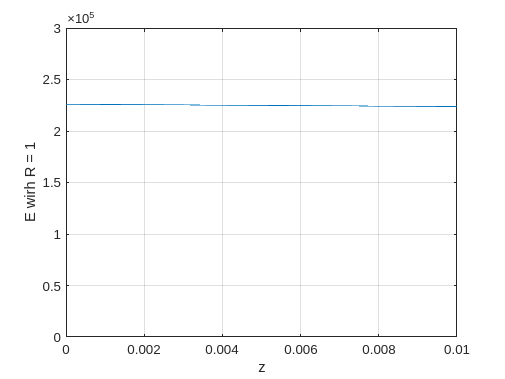

fplot(subs(E,R,1),[0 0.01])
ylim([0 3e5]), xlabel('z'), ylabel('E wirh R = 1'), grid on